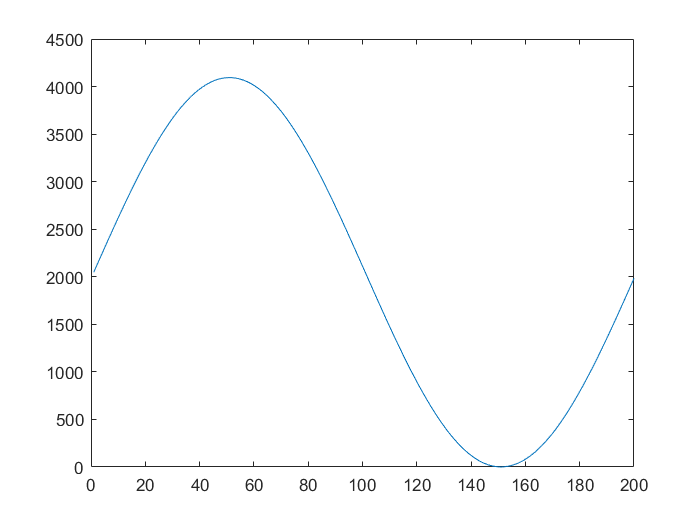

A=4096/2-1;%信号幅值
N=200;%一周期内数据点数
Ph=0;%初始相位
SineData=ceil(A*sin(Ph:2*pi/N:2*pi*(1-1/N)+Ph)+A);

plot(SineData);


Fid = fopen('SineWaveData.txt','w');
fprintf(Fid,'%d,',SineData);
fclose(Fid);

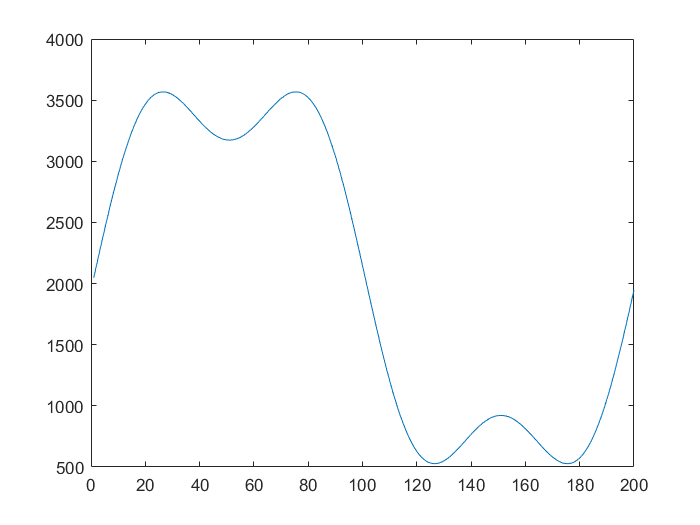

A=4096/2-1;%信号幅值
N=200;%一周期内数据点数
Ph=0;%信号初始相位
y1=sin(Ph:2*pi/N:2*pi*(1-1/N)+Ph);%基波
y3=sin(Ph:6*pi/N:6*pi*(1-1/N)+Ph);%3次谐波
SineData=ceil(0.8*A*y1+0.25*A*y3+A);
plot(SineData);


Fid = fopen('HarmonicSineWaveData.txt','w');
fprintf(Fid,'%d,',SineData);
fclose(Fid);

% 正弦波
A=4096/2-1;%信号幅值
N=200;%一周期内数据点数
Ph=0;%初始相位
SineData=ceil(A*sin(Ph:2*pi/N:2*pi*(1-1/N)+Ph)+A);
plot(SineData);

Fid = fopen('SineWave1Data.txt','w');
fprintf(Fid,'%d,',SineData);
fclose(Fid);

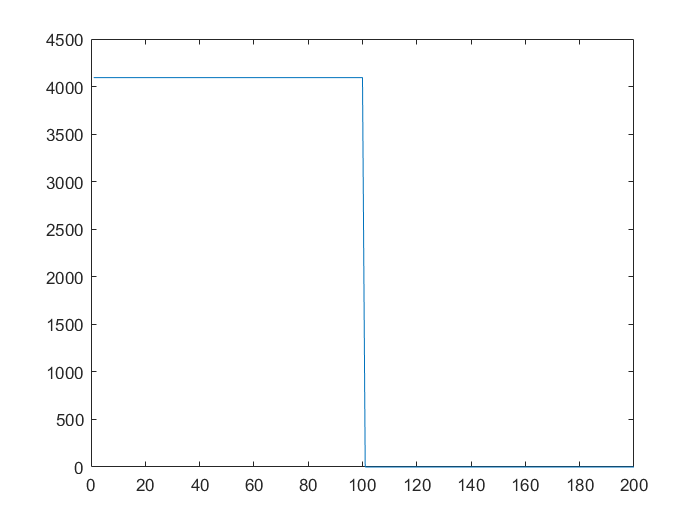

% 方波
A=4096/2-1;%信号幅值
N=200;%一周期内数据点数
Ph=0;%初始相位
SquareData=[A*2 *ones(1, N/2) zeros(1, N/2)];
plot(SquareData);

Fid = fopen('SquareWaveData.txt','w');
fprintf(Fid,'%d,',SquareData);
fclose(Fid);

% 三角波
A=4096/2-1;%信号幅值
N=200;%一周期内数据点数
Ph=0;%初始相位
riangleData=int16([linspace(0, A, N/4) linspace(A, 0, N/4) linspace(0, -A, N/4) linspace(-A, 0, N/4)] + A)

riangleData = 1×200 int16 row vector
   2047   2089   2131   2172   2214   2256   2298   2339   2381   2423   2465   2507   2548   2590   2632   2674   2715   2757   2799   2841   2883   2924   2966   3008   3050   3091   3133   3175   3217   3258   3300   3342   3384   3426   3467   3509   3551   3593   3634   3676   3718   3760   3802   3843   3885   3927   3969   4010   4052   4094


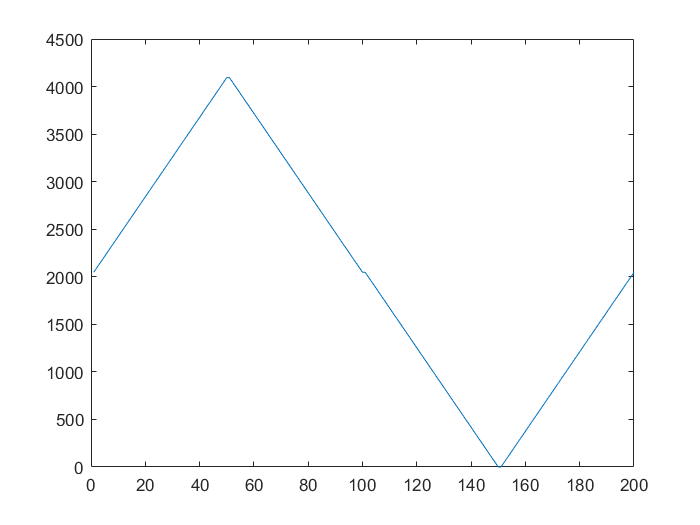

plot(TriangleData);

Fid = fopen('TriangleWaveData.txt','w');
fprintf(Fid,'%d,',TriangleData);
fclose(Fid);